## Assigment-Q6

#### Q6

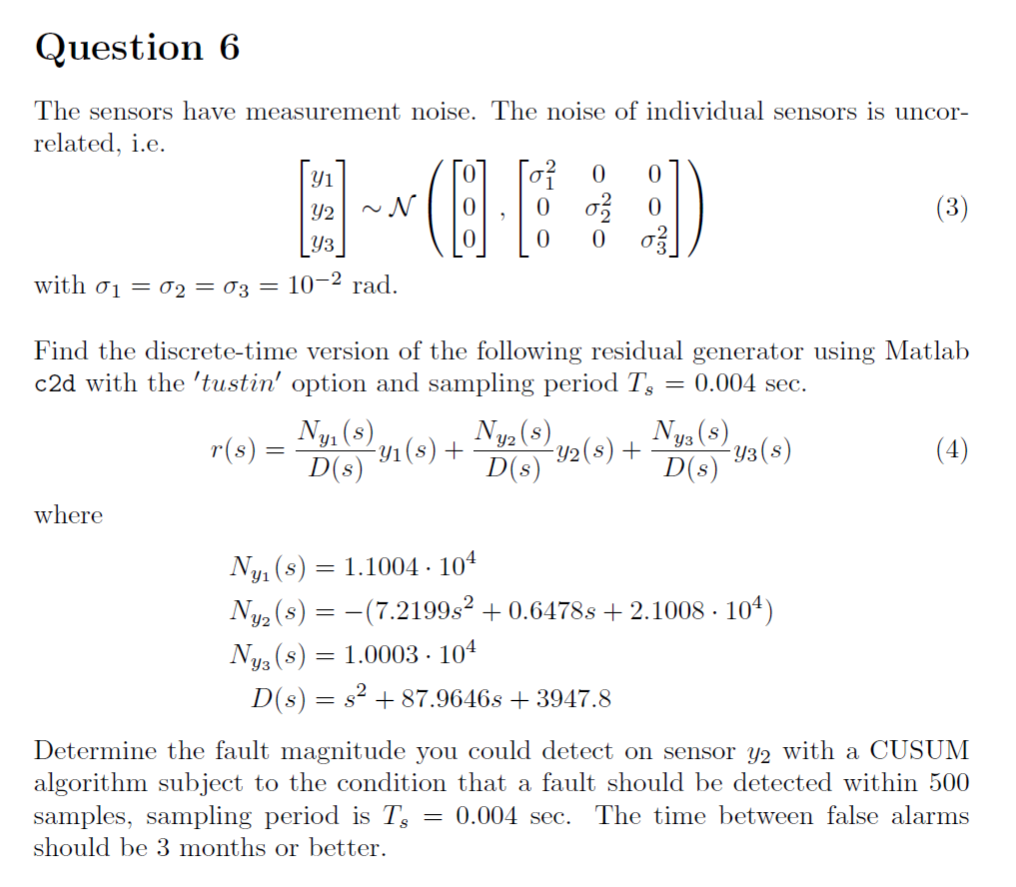

clear all
close all;
clc;
load('ECP_values.mat')
load('test1.mat','u','C','meas_fault')

% Physical system parameters
J_1 = 0.0025;                   % Disk 1 inertia kgm^2
J_2 = 0.0018;                   % Disk 2 inertia kgm^2
J_3 = 0.0018;                   % Disk 3 inertia kgm^2
k_1 = 2.7;                      % Shaft 1-2 stiffness Nm/rad
k_2 = 2.6;                      % Shaft 2-3 stiffness Nm/rad
b_1 = 0.0029;                   % Disk 1 damping and friction Nms/rad
b_2 = 0.0002;                   % Disk 2 damping and friction Nms/rad
b_3 = 0.00015;                  % Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s
wn=1;                           %natural frequency
zeta=0.96; 
%Simulation parameters:

T_s = 0.004;                           % Sampling period
f_m = 0.5;                              % Sensor fault vector (added to [y1;y2;y3])
f_m_time = 5;                         % Sensor fault occurence time

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];                  % Initial conditions

simTime = 15;                         % Simulation duration in seconds

C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];


%Sensor meassurement noise parameters:

sigma_1=10^(-2);        %Uncorrelated noise of y1
sigma_2=10^(-2);        %Uncorrelated noise of y2
sigma_3=10^(-2);        %Uncorrelated noise of y3

%Residual parameters.Numerator and denominator of the tf in continous time:

syms s

Ny1=1.1004*10^4;
Ny2=sym2poly(-(7.2199*s^2+0.6478*s+2.1008*10^4));
Ny3=1.0003*10^4;
D=sym2poly(s^2+87.9646*s+3947.8);

G_y1=tf(Ny1,D);         %TF r,y1 in continous time
G_y2=tf(Ny2,D);         %TF r,y2 in continous time
G_y3=tf(Ny3,D);         %TF r,y3 in continous time

%Residual generator in discrete time:

G_y1_d=c2d(G_y1,T_s,'tustin');         %TF r,y1 in discrete time
G_y2_d=c2d(G_y2,T_s,'tustin');         %TF r,y2 in discrete time
G_y3_d=c2d(G_y3,T_s,'tustin');         %TF r,y3 in discrete time

%CUSUM conditions:

T_D=500;                %Time to detect: in less than 500 samples
T_F=3*30*24*3600/T_s;   %Time between false alarms: more than 3 months=3*30days*24*3600/Ts samples

%Residual testing. Plots:

%H0: residual plot

switch_fault=0;
ans_0=sim('Q6_Simulink');

var_r0=max(var(ans_0.r.signals.values))%Residual variance is assumed constant

var_r0 = 0.0044

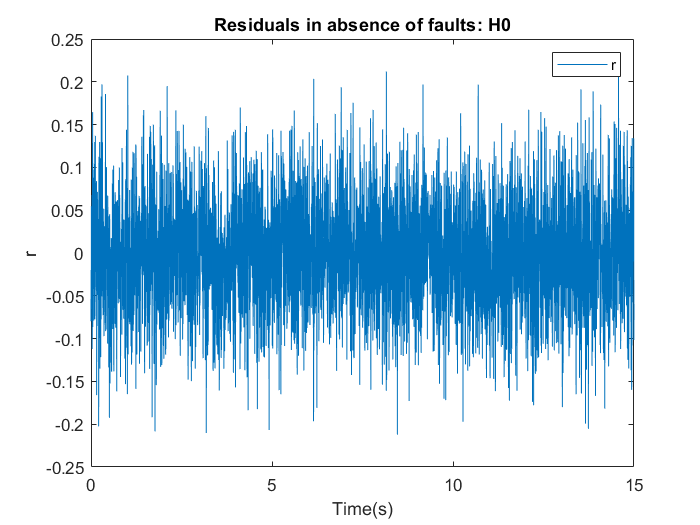

% var_r0=0.0046;
figure
plot(ans_0.r.time,ans_0.r.signals.values)
title('Residuals in absence of faults: H0')
ylabel('r')
xlabel('Time(s)')
legend('r')

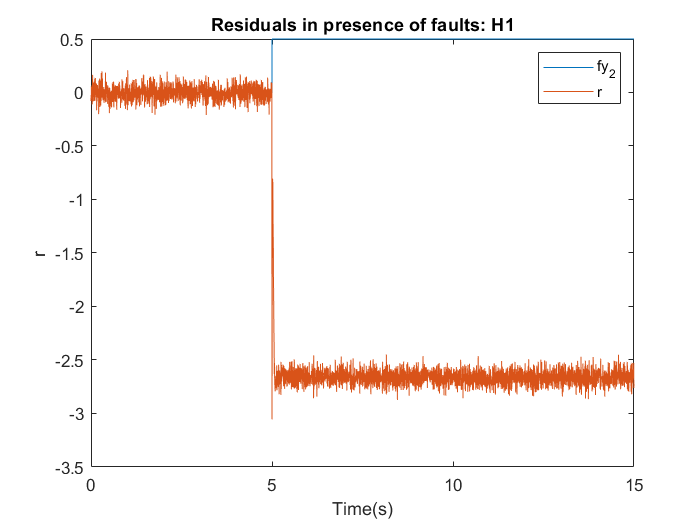

%ylim([-1 1])

%H1: residual plot

switch_fault=1;
ans_1=sim('Q6_Simulink');

figure
plot(ans_1.f_y2.time,ans_1.f_y2.signals.values,ans_1.r.time,ans_1.r.signals.values)
title('Residuals in presence of faults: H1')
ylabel('r')
xlabel('Time(s)')
legend('fy_2','r')

%ylim([-1 1])


%CUSUM design: h, mu_1

syms h mu_1

mu_0=0;
mu_s=0.5*((mu_1-mu_0)^2)/var_r0;
var_s=mu_s*2;
arg=2*mu_s*h/(var_s)+2.2232*mu_s/sqrt(var_s);

ARL_d=-T_D+(var_s/(2*mu_s^2))*(exp(-arg)+arg-1);
ARL_f=-T_F+(var_s/(2*mu_s^2))*(exp(arg)-arg-1);

eqns=[ARL_d==0, ARL_f==0];
[mu_1_sol, h_sol]=vpasolve(eqns,[mu_1 h]);
mu_1_sol=double(mu_1_sol)

mu_1_sol = -0.0172

h_sol=double(h_sol)

h_sol = 17.7171

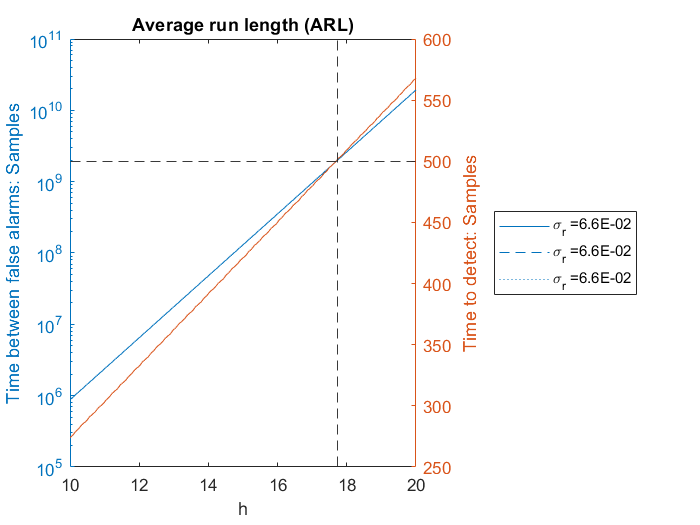

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 500
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 17.7171
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 1.9440e+09
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 17.7171
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties



%Plot to prove the optimality of the solution:

sigma_r_min=+sqrt(var_r0);
sigma_r_max=+sqrt(var_r0);

h_min=10;
h_max=20;

ARL_design_Q6(mu_1_sol, mu_0, sigma_r_min, sigma_r_max, h_min, h_max,T_D,T_F,h_sol)


% figure 
% plot(t,error*(-mu_1_sol))

%CUSUM resoult plot:

f_m=mu_1_sol/(-5.3)

f_m = 0.0033

switch_fault=1;
ans_2=sim('Q6_Simulink.slx');

r=ans_2.r.signals.values;
g=zeros(1,size(r,1));
error=zeros(1,size(r,1));

for i=2:size(r,1)
    s=((mu_1_sol-mu_0)/(var_r0))*(r(i-1)-(mu_1_sol-mu_0)/2);
    g(i)=max(0,g(i-1)+s);
    error(i)=g(i)>h_sol;
    if(error(i)-error(i-1)==1)
        index_f=i
    end
end

index_f = 1819


t=0:size(r,1)-1;

figure
plot(t,g,t,error*h_sol)
xline(f_m_time/T_s+T_D,'linestyle','--');
xline(index_f(1,1),'linestyle','--');
yline(h_sol,'linestyle','--')

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 17.7171
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


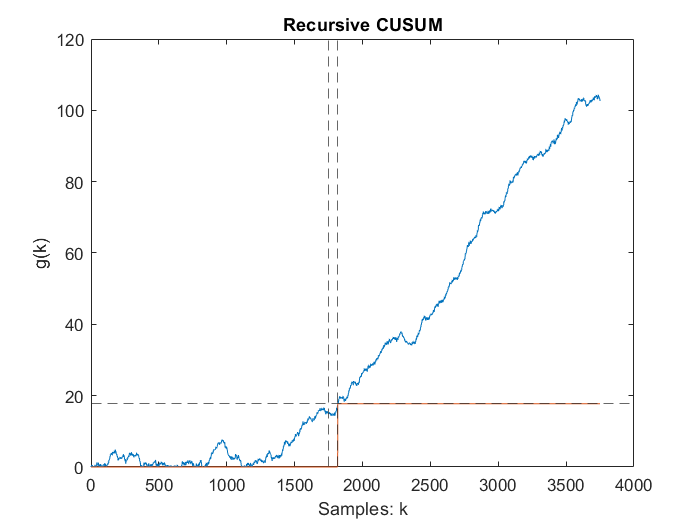

title('Recursive CUSUM')
xlabel('Samples: k')
ylabel('g(k)')


%%%LABORATORY PART
sims=sim('Lab6')

sims =   Simulink.SimulationOutput:

                H_cusum: [1x1 struct] 
                   f_y2: [1x1 struct] 
                g_cusum: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                     r1: [1x1 struct] 
                   tout: [3081x1 double] 
                      y: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


fig=figure

fig =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties



yyaxis left
plot(sims.H_cusum.time,reshape(sims.H_cusum.signals.values,1,size(sims.H_cusum.signals.values,3)),'r','LineWidth',0.8)
hold on 
b=plot(sims.r1.time,sims.r1.signals.values,'b-')

b =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×3001 double]
              YData: [1×3001 double]
              ZData: [1×0 double]

  Show all properties


ylim([-0.4 1.2])
ylabel('r and H')
hold on
yyaxis right
a=plot(sims.g_cusum.time,sims.g_cusum.signals.values,'k','LineWidth',1)

a =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×3001 double]
              YData: [1×3001 double]
              ZData: [1×0 double]

  Show all properties


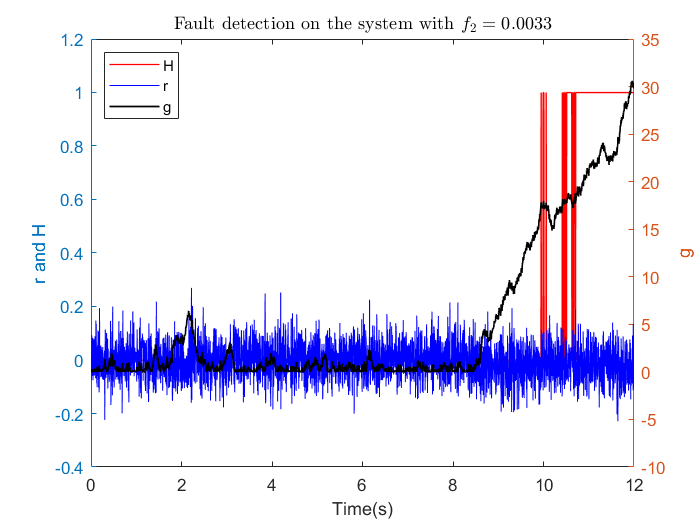

ylabel('g')
ylim([-10 35])

title('Fault detection on the system with $f_2=0.0033$','Interpreter','latex')

xlabel('Time(s)')
legend('H','r','g','Location','northwest')

saveas(fig,'CUSUM_Q6.png')

%As it can be seen, the decision value H is jumping as the value of g is
%alternating around the threshold value. The fault is strongly detected at
%t=10.7 seconds. Time of faults occurence is 8.5s.